# BMW VALUATION - MONTECARLO SIMULATION

Monte Carlo Simulation for a DCF Model Valuation (Conservative Scenario)

This script performs a Monte Carlo simulation to estimate the fair value  of BMW based on a highly conservative DCF model, as said in the presentation, our expectation aren't really optimstic.

It's possible to change values and ranges to see what changes.

% Step 1: Load Known Free Cash Flow (FCF) Data from Excel file
% Assuming 'DAX Historical Data-2.xlsx' has a column 'Change' with monthly returns.
DAX = readtable('DAX Historical Data.xlsx');

DAX = DAX.Change; % Extract the market return data
% Known FCFs for the first 5 years (as given)
FCF = [12370, 12958, 13808, 14472, 15250];

% Step 2: Define Parameters
% Lowered market return expectations and increased debt cost further
mean_market_return = mean(DAX) * 12; % Further reduced annualized mean return
std_market_return = std(DAX) * sqrt(12); % Further reduced annualized standard deviation

% Today's fixed parameters for CAPM and WACC calculation
risk_free_rate = 0.0282; % Today's risk-free rate
beta = 1.08; % Beta for CAPM
r_d = 0.05; % Increased cost of debt
T = 0.3; % Corporate tax rate

% Increased debt level and reduced equity
E = 45000; % Reduced value of equity for more conservative approach
D = 220000; % Further increased value of debt

% Results of previous Excel analysis for comparison
previous_EV = 143289; % Previous EV value from Excel analysis
previous_FV = 76.42;  % Previous FV per share from Excel analysis

% Pre-allocate arrays for DCF and EV values
EV = zeros(num_simulations, 1);
num_simulations = 1000; % Number of Monte Carlo iterations

% Market return bounds for sampling
market_return_lower = r_d; % Ensure lower bound is positive, at least equal to debt cost
market_return_upper = quantile(DAX,0.9)*12; % Upper bound is limited to a certain quantile of returns distribution (annualized)

% Highly conservative growth rate bounds for terminal value
g_lower = -0.01;   % Lower bound
g_upper = 0.01;  % Upper bound 

% Step 3: Monte Carlo Simulation Loop
for i = 1:num_simulations
    % Generate random sample for market return within the specified range,
    % supposing normally distributed returns, but can't be negative
    market_return = market_return_lower + rand * (market_return_upper - market_return_lower);

    % Calculate cost of equity (r_e) using CAPM
    r_e = risk_free_rate + beta * (market_return - risk_free_rate);
    
    % Calculate WACC with more pessimistic values
    WACC = (E / (E + D)) * r_e + (D / (E + D)) * r_d * (1 - T);
    
    % Generate random sample for perpetual growth rate g within specified range
    g = g_lower + (g_upper - g_lower) * rand;

    % Calculate the DCF value using known FCFs and terminal value
    % Discount each of the known FCFs for the first 5 years
    PV_FCF = sum(FCF ./ (1 + WACC).^(1:5));
    
    % Calculate Terminal Value at year 5 and discount it back to present
    Terminal_Value = (FCF(end) * (1 + g)) / (WACC - g); % Perpetual growth formula
    PV_Terminal_Value = Terminal_Value / (1 + WACC)^5; % Discount to present
    
    % Total DCF value (Enterprise Value) for this simulation
    EV(i) = PV_FCF + PV_Terminal_Value;
end


% Step 4: Statistical Analysis for Enterprise Value (EV)
% Using t-distribution to calculate the 95% confidence interval for EV
mean_EV = mean(EV);
std_EV = std(EV);
n = length(EV); % Sample size
alpha = 0.05; % 95% confidence level

% T-distribution critical value
t_value = tinv(1 - alpha/2, n - 1);
margin_of_error_EV = t_value * (std_EV / sqrt(n));
conf_interval_EV = [mean_EV - margin_of_error_EV, mean_EV + margin_of_error_EV];
median_EV = median(EV);

% Display results for EV
fprintf('Mean EV : %.2f\n', mean_EV);

Mean EV : 163422.54


fprintf('Standard Deviation of EV : %.2f\n', std_EV);

Standard Deviation of EV : 83152.55


fprintf('95%% Confidence Interval for EV: [%.2f, %.2f]\n', conf_interval_EV(1), conf_interval_EV(2));

95% Confidence Interval for EV: [158262.54, 168582.55]


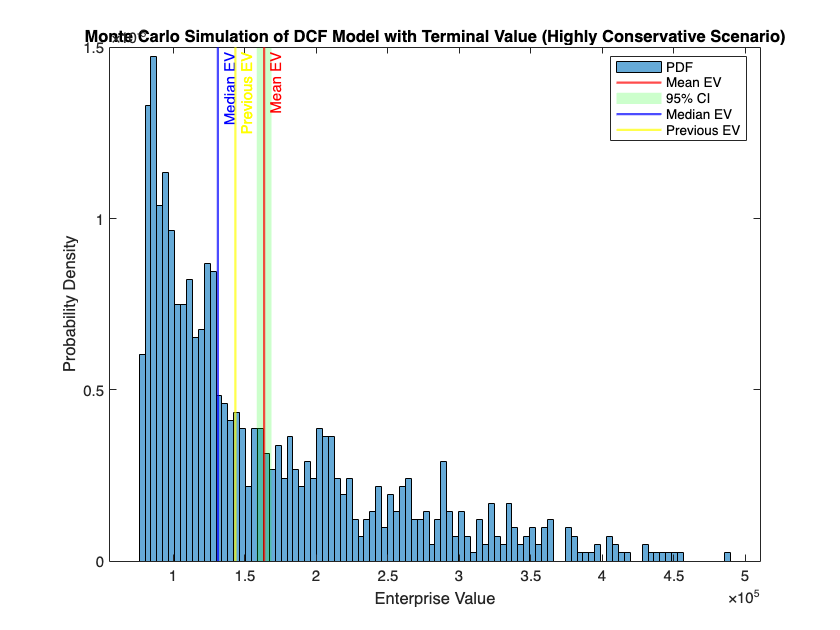

% Plot the distribution of Enterprise Values with confidence interval
figure;
histogram(EV, 100, 'Normalization', 'pdf');
xlabel('Enterprise Value');
ylabel('Probability Density');
title('Monte Carlo Simulation of DCF Model with Terminal Value (Highly Conservative Scenario)');
% Add shaded area for 95% confidence interval
hold on;
xline(mean_EV, 'r', 'LineWidth', 1.5, 'Label', 'Mean EV');
fill([conf_interval_EV(1), conf_interval_EV(1), conf_interval_EV(2), conf_interval_EV(2)], ...
     [0, max(ylim), max(ylim), 0], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xline(median_EV, 'b', 'LineWidth', 1.5, 'Label', 'Median EV');
xline(previous_EV, 'y', 'LineWidth', 1.5, 'Label', 'Previous EV');
legend({'PDF', 'Mean EV', '95% CI', 'Median EV', 'Previous EV'}, 'Location', 'best');
hold off;

% Step 5: Calculate Fair Value per Share
E_adjusted = (EV - 95147) * 1e6; % Adjusted for debt or other adjustments and scaled by a million
n_Shares = 630000000; % Number of shares outstanding
FV = E_adjusted / n_Shares;

% Statistical Analysis for Fair Value (FV)
% Using t-distribution to calculate the 95% confidence interval for FV per share
mean_FV = mean(FV);
std_FV = std(FV);
margin_of_error_FV = t_value * (std_FV / sqrt(n));
conf_interval_FV = [mean_FV - margin_of_error_FV, mean_FV + margin_of_error_FV];
median_FV = median(FV);

% Display Fair Value results
fprintf('Mean FV per Share: %.2f\n', mean_FV);

Mean FV per Share: 108.37


fprintf('Standard Deviation of FV per Share: %.2f\n', std_FV);

Standard Deviation of FV per Share: 131.99


fprintf('95%% Confidence Interval for FV per Share: [%.2f, %.2f]\n', conf_interval_FV(1), conf_interval_FV(2));

95% Confidence Interval for FV per Share: [100.18, 116.56]


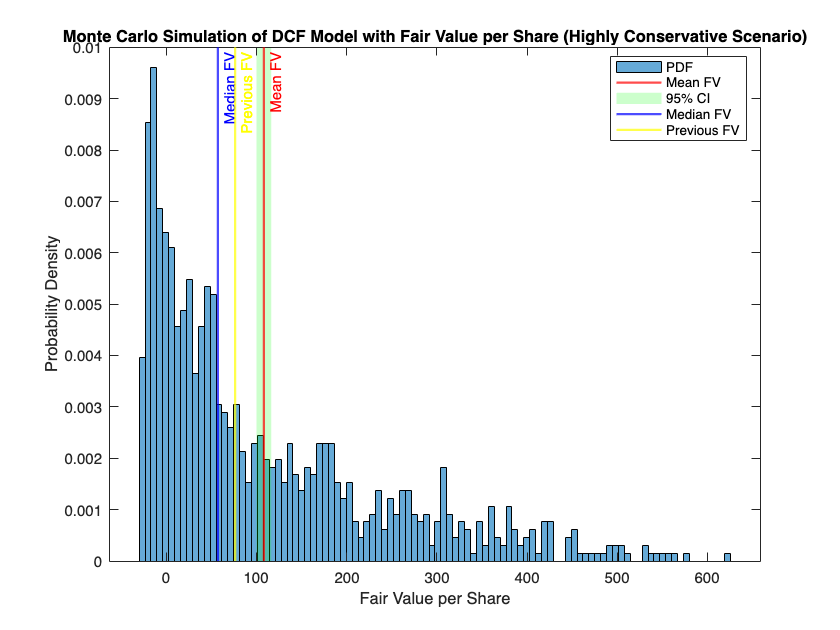

% Plot the distribution of Fair Value per Share with confidence interval
figure;
histogram(FV, 100, 'Normalization', 'pdf');
xlabel('Fair Value per Share');
ylabel('Probability Density');
title('Monte Carlo Simulation of DCF Model with Fair Value per Share (Highly Conservative Scenario)');

% Add shaded area for 95% confidence interval
hold on;
xline(mean_FV, 'r', 'LineWidth', 1.5, 'Label', 'Mean FV');
fill([conf_interval_FV(1), conf_interval_FV(1), conf_interval_FV(2), conf_interval_FV(2)], ...
     [0, max(ylim), max(ylim), 0], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xline(median_FV, 'b', 'LineWidth', 1.5, 'Label', 'Median FV');
xline(previous_FV, 'y', 'LineWidth', 1.5, 'Label', 'Previous FV');
legend({'PDF', 'Mean FV', '95% CI', 'Median FV', 'Previous FV'}, 'Location', 'best');
hold off;

MEDIAN CONFIDENCE INTERVAL

Mean is not really significant, in a MonteCarlo simulation there are many outliers

% Bootstrap settings
num_bootstrap = 1000; % Number of bootstrap samples
bootstrap_medians_EV = zeros(num_bootstrap, 1);
bootstrap_medians_FV = zeros(num_bootstrap, 1);

% Bootstrap for EV
for i = 1:num_bootstrap
    resampled_EV = randsample(EV, n, true); % Resample with replacement
    bootstrap_medians_EV(i) = median(resampled_EV); % Median of resampled data
end

% 95% Confidence Interval for EV median
conf_interval_median_EV = quantile(bootstrap_medians_EV, [0.025, 0.975]);

% Display results for EV median
fprintf('Median EV : %.2f\n', median_EV);

Median EV : 131185.20


fprintf('95%% Confidence Interval for Median EV: [%.2f, %.2f]\n', ...
        conf_interval_median_EV(1), conf_interval_median_EV(2));

95% Confidence Interval for Median EV: [126273.72, 138276.07]


% Bootstrap for FV
for i = 1:num_bootstrap
    resampled_FV = randsample(FV, n, true); % Resample with replacement
    bootstrap_medians_FV(i) = median(resampled_FV); % Median of resampled data
end

% 95% Confidence Interval for FV median
conf_interval_median_FV = quantile(bootstrap_medians_FV, [0.025, 0.975]);

% Display results for FV median
fprintf('Median FV per Share: %.2f\n', median_FV);

Median FV per Share: 57.20


fprintf('95%% Confidence Interval for Median FV per Share: [%.2f, %.2f]\n', ...
        conf_interval_median_FV(1), conf_interval_median_FV(2));

95% Confidence Interval for Median FV per Share: [49.47, 67.47]


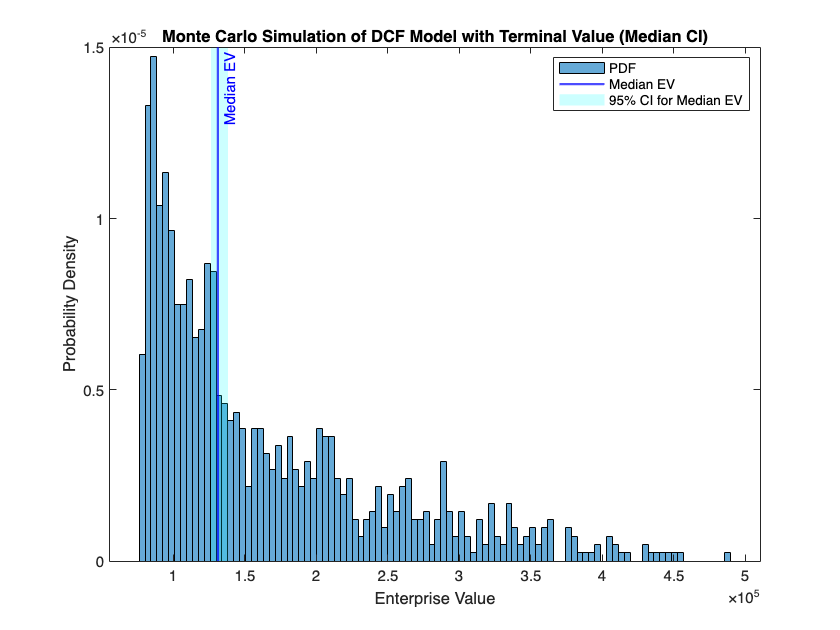

% Plotting the distribution with confidence intervals for the median

% EV Plot
figure;
histogram(EV, 100, 'Normalization', 'pdf');
xlabel('Enterprise Value');
ylabel('Probability Density');
title('Monte Carlo Simulation of DCF Model with Terminal Value (Median CI)');

hold on;
xline(median_EV, 'b', 'LineWidth', 1.5, 'Label', 'Median EV');
fill([conf_interval_median_EV(1), conf_interval_median_EV(1), conf_interval_median_EV(2), conf_interval_median_EV(2)], ...
     [0, max(ylim), max(ylim), 0], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
legend({'PDF', 'Median EV', '95% CI for Median EV'}, 'Location', 'best');
hold off;

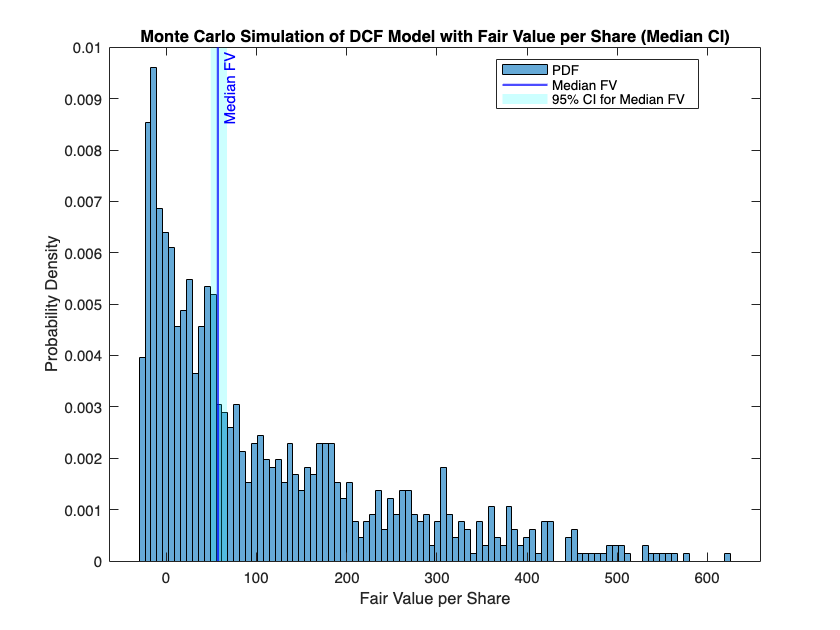

% FV Plot
figure;
histogram(FV, 100, 'Normalization', 'pdf');
xlabel('Fair Value per Share');
ylabel('Probability Density');
title('Monte Carlo Simulation of DCF Model with Fair Value per Share (Median CI)');

hold on;
xline(median_FV, 'b', 'LineWidth', 1.5, 'Label', 'Median FV');
fill([conf_interval_median_FV(1), conf_interval_median_FV(1), conf_interval_median_FV(2), conf_interval_median_FV(2)], ...
     [0, max(ylim), max(ylim), 0], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
legend({'PDF', 'Median FV', '95% CI for Median FV'}, 'Location', 'best');
hold off;